syms x1 x2 x3 x4 u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
T=0.05;% tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)  <- ESTADO NO LINEAL
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);

% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;

% Jacobiano simbólico
As=[diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4);...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4);...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4);...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)];

Bs=[diff(f1,u);diff(f2,u);diff(f3,u);diff(f4,u)];

C=[1 0 0 0];
D=[0];

% Ampliar A y B para acción integral
Aa = [As, zeros(4,1); -C, 0];
Bb = [Bs; 0];

%% Parámetros del controlador
zeta = 0.8;
tsdes = 2;
wn = 4.6 / (zeta * tsdes);
sistReferencia = tf([0 0 1],[1 2*zeta*wn wn^2]);
polosz = [pole(sistReferencia)' -1 -6 -5];

%% GAIN SCHEDULING BASADO EN EL ÁNGULO DEL PÉNDULO (x3 = theta)
% Cambiamos phi_vector por theta_vector
theta_vector = deg2rad(-70:1:70);  % Rango amplio del ángulo del péndulo
Ka = zeros(length(theta_vector), 5);  % matriz de ganancias

fprintf('Calculando ganancias para %d puntos de operación...\n', length(theta_vector));

Calculando ganancias para 141 puntos de operación...



for i = 1:length(theta_vector)
    theta_i = theta_vector(i);
    
    % Estado de equilibrio
    x1ss = 0;        % brazo en posición inicial
    x2ss = 0;        % velocidad brazo = 0
    x3ss = theta_i;  % ángulo del péndulo (variable de scheduling)
    x4ss = 0;        % velocidad péndulo = 0

    % Entrada de equilibrio
    uss = (3*g*la*mp*sin(2*x3ss))/8;

    % Evaluar matrices linealizadas
    A_num = double(subs(Aa, [x1, x2, x3, x4, u], [x1ss, x2ss, x3ss, x4ss, uss]));
    B_num = double(subs(Bb, [x1, x2, x3, x4, u], [x1ss, x2ss, x3ss, x4ss, uss]));

    % Verificar controlabilidad
    if rank(ctrb(A_num, B_num)) == size(A_num,1)
        Ka(i,:) = acker(A_num, B_num, polosz);
    else
        warning("Sistema no controlable para theta = %.2f rad (%.1f°)", theta_i, rad2deg(theta_i));
        Ka(i,:) = Ka(max(1,i-1),:);  % usar ganancia anterior si no es controlable
    end
    
    % Mostrar progreso
    if mod(i,5) == 0
        fprintf('Completado: %d/%d\n', i, length(theta_vector));
    end
end

Completado: 5/141
Completado: 10/141
Completado: 15/141
Completado: 20/141
Completado: 25/141
Completado: 30/141
Completado: 35/141
Completado: 40/141
Completado: 45/141
Completado: 50/141
Completado: 55/141
Completado: 60/141
Completado: 65/141
Completado: 70/141
Completado: 75/141
Completado: 80/141
Completado: 85/141
Completado: 90/141
Completado: 95/141
Completado: 100/141
Completado: 105/141
Completado: 110/141
Completado: 115/141
Completado: 120/141
Completado: 125/141
Completado: 130/141
Completado: 135/141
Completado: 140/141


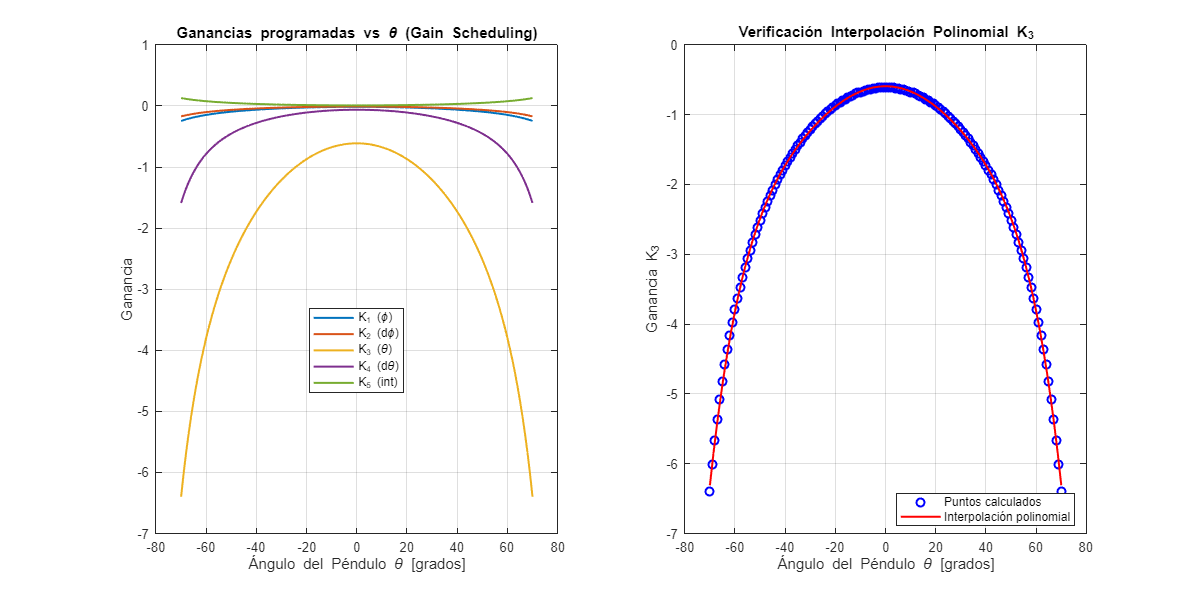


%% Separación de ganancias individuales
K1 = Ka(:,1);  % asociado a x1 (phi)
K2 = Ka(:,2);  % asociado a x2 (dphi)
K3 = Ka(:,3);  % asociado a x3 (theta) 
K4 = Ka(:,4);  % asociado a x4 (dtheta)
K5 = Ka(:,5);  % asociado al integrador

%% Ajuste polinomial de cada ganancia para interpolación
% Usamos grado 6 para capturar mejor la no linealidad
grado_poly = 6;
polk1 = polyfit(theta_vector, K1, grado_poly);
polk2 = polyfit(theta_vector, K2, grado_poly);
polk3 = polyfit(theta_vector, K3, grado_poly);
polk4 = polyfit(theta_vector, K4, grado_poly);
polk5 = polyfit(theta_vector, K5, grado_poly);

%% Visualización de las ganancias vs ángulo del péndulo
figure('Position', [100, 100, 1200, 600]);
subplot(1,2,1)
plot(rad2deg(theta_vector), Ka, 'LineWidth', 1.5)
legend('K_1 (\phi)','K_2 (d\phi)','K_3 (\theta)','K_4 (d\theta)','K_5 (int)', 'Location', 'best')
xlabel('Ángulo del Péndulo \theta [grados]')
ylabel('Ganancia')
title('Ganancias programadas vs \theta (Gain Scheduling)')
grid on

% Verificación del ajuste polinomial
subplot(1,2,2)
theta_fine = linspace(min(theta_vector), max(theta_vector), 100);
K3_interp = polyval(polk3, theta_fine);
plot(rad2deg(theta_vector), K3, 'bo', 'MarkerSize', 6, 'LineWidth', 1.5)
hold on
plot(rad2deg(theta_fine), K3_interp, 'r-', 'LineWidth', 1.5)
xlabel('Ángulo del Péndulo \theta [grados]')
ylabel('Ganancia K_3')
title('Verificación Interpolación Polinomial K_3')
legend('Puntos calculados', 'Interpolación polinomial', 'Location', 'best')
grid on

%% SIMULACIÓN CON GAIN SCHEDULING BASADO EN THETA
Ts = 0.1;        
Tspan = 70;       
time = 0:Ts:(Tspan - Ts);
Ns = length(time);

%% Condiciones iniciales
x = [0; 0; 0; 0];    % Estado inicial con pequeña perturbación en theta
int_err = 0;         
r = 0;               

%% Acumuladores
x_acc = zeros(4, Ns);
u_acc = zeros(1, Ns);
y_acc = zeros(1, Ns);
e_acc = zeros(1, Ns);
re = zeros(1, Ns);
theta_acc = zeros(1, Ns);  % Para visualizar el ángulo del péndulo

% Guardar condiciones iniciales
x_acc(:, 1) = x;
y_acc(1) = x(1);
theta_acc(1) = x(3);
re(1) = r;

fprintf('\nIniciando simulación...\n');


Iniciando simulación...


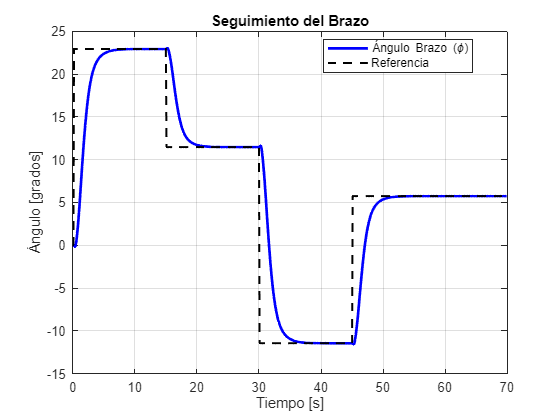



params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0;


% BUCLE DE SIMULACIÓN
for i = 1:Ns-1
    % Actualización escalonada de la referencia
    if time(i) >= 0.1 && time(i-1) < 0.1
        r = 0.4;
    elseif time(i) >= 15 && time(i-1) < 15
        r = 0.2;
    elseif time(i) >= 30 && time(i-1) < 30
        r = -0.2;
    elseif time(i) >= 45 && time(i-1) < 45
        r = 0.1;
    end

    y = x(1);               % Salida medida: ángulo del brazo (phi)
    theta = x(3);           % Ángulo del péndulo (variable de scheduling)
    HU(i) = abs(theta-floor(theta/(2*pi))*2*pi);

    % GAIN SCHEDULING: Ganancias interpoladas según theta (NO phi)
    
    theta_sat = max(min(theta, max(theta_vector)), min(theta_vector));
    if abs(theta-floor(theta/(2*pi))*2*pi) < deg2rad(25)  || abs(theta-floor(theta/(2*pi))*2*pi) > deg2rad(335)  && abs(x(4)) < deg2rad(150)
        e = r - y;              % Error
        int_err = int_err + Ts * e;
        Kad_gs = [polyval(polk1, theta_sat), polyval(polk2, theta_sat), ...
                  polyval(polk3, theta_sat), polyval(polk4, theta_sat), ...
                  polyval(polk5, theta_sat)];
    
        % Control con ganancia programada
        u = -Kad_gs * [x; int_err];
    else
        u = 0.7*swing_up_energy_controller(x, params);
        int_err = 0; % Resetear el integrador
    end
    % Simulación de la planta no lineal
    [~, x_out] = ode45(@(t, x) complex_rot_pend(t, x, [], u), [0 Ts], x);
    x = x_out(end, :)';

    % Guardar datos
    x_acc(:, i+1) = x;
    u_acc(i+1) = u;
    y_acc(i+1) = x(1);
    theta_acc(i+1) = x(3);
    e_acc(i+1) = e;
    re(i+1) = r;
end

%% Gráficas Mejoradas
figure;
plot(time, x_acc(1,:)*180/pi, 'blue', 'LineWidth', 2)
hold on
plot(time, re*180/pi, 'black--', 'LineWidth', 1.5);
ylabel('Ángulo [grados]')
xlabel('Tiempo [s]')
legend('Ángulo Brazo (\phi)', 'Referencia', 'Location', 'best');
title('Seguimiento del Brazo')
grid on

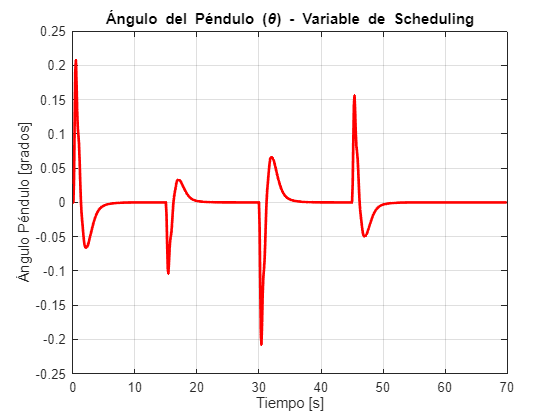


figure;
plot(time, x_acc(3,:)*180/pi, 'red', 'LineWidth', 2)
ylabel('Ángulo Péndulo [grados]')
xlabel('Tiempo [s]')
title('Ángulo del Péndulo (\theta) - Variable de Scheduling')
grid on

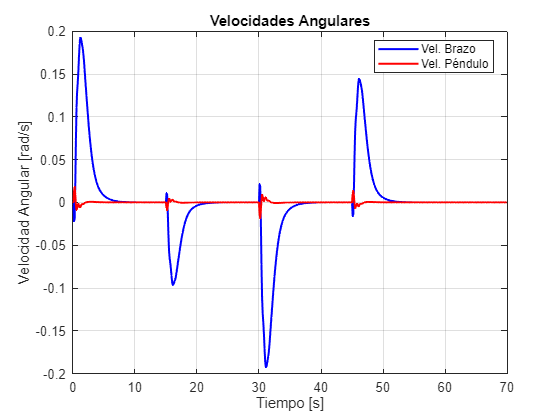


figure;
plot(time, x_acc(2,:), 'blue', 'LineWidth', 1.5)
hold on
plot(time, x_acc(4,:), 'red', 'LineWidth', 1.5)
ylabel('Velocidad Angular [rad/s]')
xlabel('Tiempo [s]')
legend('Vel. Brazo', 'Vel. Péndulo', 'Location', 'best');
title('Velocidades Angulares')
grid on

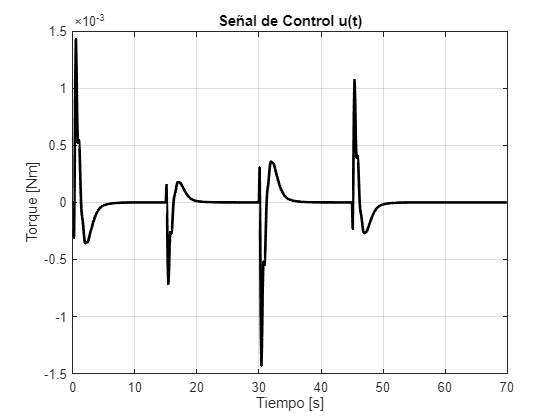


figure;
plot(time, u_acc, 'k', 'LineWidth', 2)
ylabel('Torque [Nm]')
xlabel('Tiempo [s]')
title('Señal de Control u(t)')
grid on

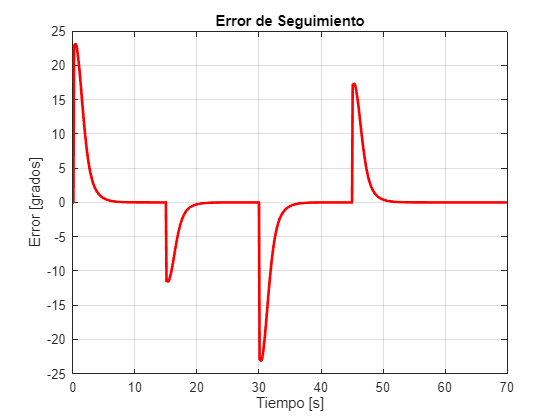


figure;
plot(time, e_acc*180/pi, 'r', 'LineWidth', 2)
xlabel('Tiempo [s]')
ylabel('Error [grados]')
title('Error de Seguimiento')
grid on

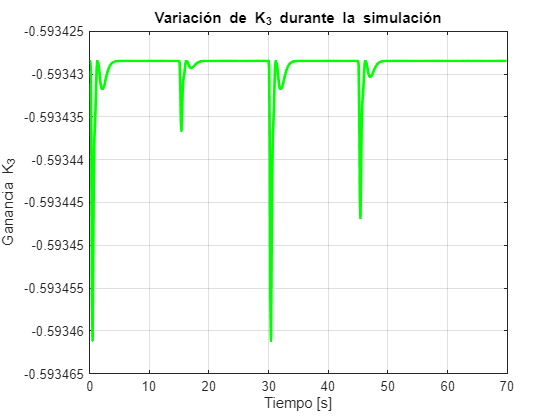


figure;
% Ganancias vs tiempo (mostrando la variación debido al scheduling)
K3_tiempo = zeros(size(time));
for i = 1:length(time)
    theta_i = theta_acc(i);
    theta_sat = max(min(theta_i, max(theta_vector)), min(theta_vector));
    K3_tiempo(i) = polyval(polk3, theta_sat);
end
plot(time, K3_tiempo, 'g', 'LineWidth', 2)
xlabel('Tiempo [s]')
ylabel('Ganancia K_3')
title('Variación de K_3 durante la simulación')
grid on


fprintf('Simulación completada.\n');

Simulación completada.


fprintf('Rango de theta durante simulación: [%.2f, %.2f] grados\n', ...
        min(theta_acc)*180/pi, max(theta_acc)*180/pi);

Rango de theta durante simulación: [-0.21, 0.21] grados


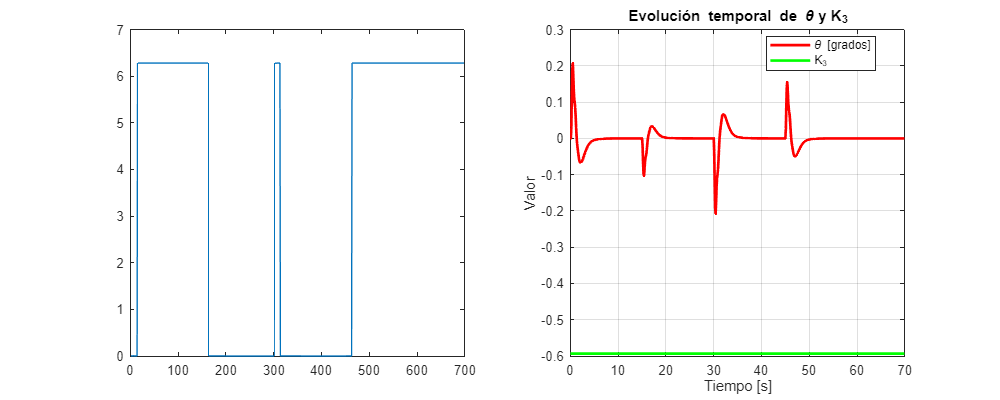


%% COMPARACIÓN: Visualizar cambio en las ganancias
figure('Position', [100, 100, 1000, 400]);
subplot(1,2,1)
plot(rad2deg(theta_vector), K3, 'bo-', 'LineWidth', 2, 'MarkerSize', 6)
xlabel('Ángulo del Péndulo \theta [grados]')
ylabel('Ganancia K_3')
title('K_3 vs Ángulo del Péndulo')
grid on
plot(HU)
subplot(1,2,2)
plot(time, theta_acc*180/pi, 'r-', 'LineWidth', 2)
hold on
plot(time, K3_tiempo, 'g-', 'LineWidth', 2)
xlabel('Tiempo [s]')
ylabel('Valor')
legend('\theta [grados]', 'K_3', 'Location', 'best')
title('Evolución temporal de \theta y K_3')
grid on